### Setup for RIR generator

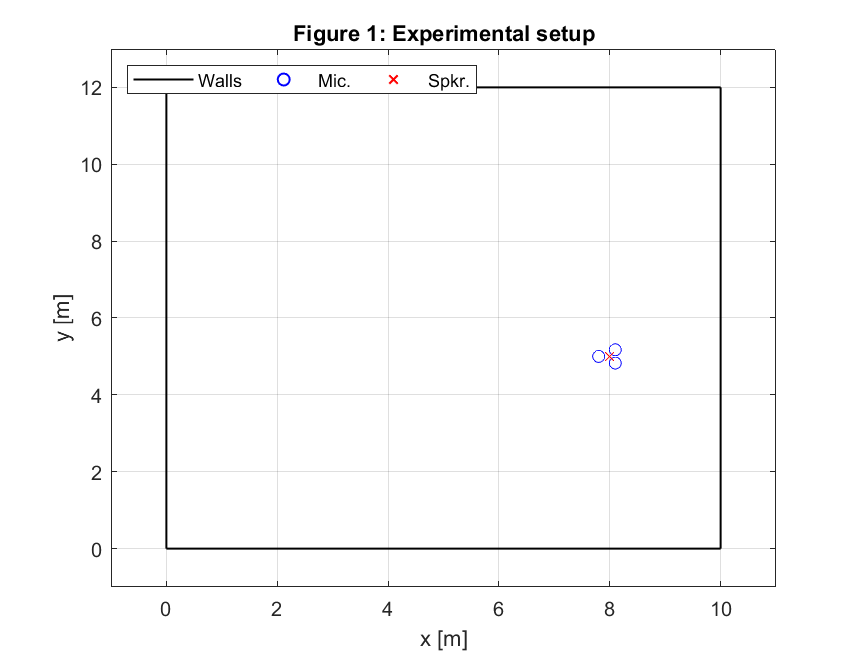

clear variables

addpath(genpath('lib'));
addpath(genpath('data'));
addpath('RIR_generator');
addpath('Exploration_scheme');
addpath('Echolocation');


% Defining room dimensions
roomConstants = struct( ...
    'length', 10, ...
    'width', 12, ...
    'height', 10 ...
    );

roomConstants.robotPos = [8, 5, 5];

setup = defaultMiscSetup([]);
setup = defaultSignalSetup(setup);
setup = defaultArraySetup(setup);
setup = defaultRirGenSetup(setup);
setup = defaultRoomSetup(setup, roomConstants);
setup = defaultEmSetup(setup);

setup.EM.noiseWeighting = 1;
setup.EM.plotIterations = 1; 
setup.EM.directPathFlag = 0;
setup.signal.snr = [40 40 40 -40];
setup.signal.sdnr = 80;
setup.EM.maximumDistance = 2;
setup.EM.nRefl = 1;
setup.EM.nIter = 20;

plotRoom(setup);

### Setup for echolocation algorithm

% Struct for often used constants
echolocationConstants = struct( ...
    'Samplerate', setup.signal.sampFreq, ...
    'AmountOfMicrophones', setup.array.micNumber, ...
    'UCARadius', setup.array.micRadius, ...
    'SpeedOfSound', setup.room.soundSpeed, ...
    'AlphaOffset', setup.array.micOffset, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 601 ...
    );


% Distance parameters
MinDistance = setup.EM.minimumDistance;
MaxDistance = setup.EM.maximumDistance;



Generate RIRS

rirs = generateRirs(setup);
%plotRIRs(rirs);

% The signals involved in the considered method are:
%   - Probe signal: White Gaussian noise burst
%   - Noise signal: Diffuese rotor noise from drone 
%       + white Gaussian sensor noise

Generate signals

signals = generateSignals(rirs,[],setup);
ProbeSound = signals.clean;
%plotSignals(signals);

### Precalculations for echolocation algorithm


% Calculate angular position of microphones
echolocationConstants.Betas = UCAangles(echolocationConstants.AmountOfMicrophones, echolocationConstants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), echolocationConstants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, echolocationConstants.AmountOfTaus) * 2 / echolocationConstants.SpeedOfSound * echolocationConstants.Samplerate; % In samples
Omegas = ceil(linspace(0, echolocationConstants.Samplerate, echolocationConstants.AmountOfOmegas)); % In Hz
OmegasAngular = Omegas * 2 * pi; % In rad/sample
OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) = OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) - echolocationConstants.Samplerate * 2 * pi;
%OmegasAngular(Constants.AmountOfOmegas/2:end) = flip(OmegasAngular(Constants.AmountOfOmegas/2:end)) - Constants.Samplerate * pi

% Find the one sided FFT of the received sound
%nFFT = 2^nextpow2(length(ProbeSound));
nFFT = echolocationConstants.AmountOfOmegas;
ProbeFFT = TwoSidedFFT(ProbeSound, echolocationConstants, ...
    "nFFT", nFFT, "Plot", false);

% Define linspaces for indexing Omegas
OmegasBinIndices = linspace(0, echolocationConstants.AmountOfOmegas-1, echolocationConstants.AmountOfOmegas);
OmegasFFTIndices = ceil(Omegas * nFFT / echolocationConstants.Samplerate);
OmegasFFTIndices(1) = 1;

% Calculate Zbar
Zbar = CalculateZbar(ProbeFFT(OmegasFFTIndices), Phis, Taus, OmegasBinIndices, echolocationConstants);


### Setup of simulation environment

% Create objects [x,y,label]

%% Create a multi-robot environment
numRobots = 2;
env = MultiRobotEnv(numRobots);
env.robotRadius = repelem(0.30, 1, numRobots);
env.hasObjects = true;
env.hasLidar = repelem(true, 1, numRobots);
env.showTrajectory = ones(1,numRobots);
env.robotColors = rand(numRobots,3);
env.plotSensorLines = false; % So the sensor lines don't dominate the visuals

% env.objectColors = repelem([1 0 0], numRobots, 1);
% 
% for idx = 1:numRobots
%     env.objectMarkers(idx) = '*';
% end
MaxReflectors = 30; 

objects = repelem([999 999 1], MaxReflectors, 1);
env.objectColors = repelem([1 0 0], MaxReflectors, 1);
env.objectMarkers = repelem('c', 1, MaxReflectors);


% Load a map as png and apply it to the environment
resolution = 50; % Smaller resolution corresponds to bigger map, and vice versa

image = imread('Soundlab_map.png');
grayimage = rgb2gray(image);
bwimage = grayimage < 0.5;

height = size(image, 1)/resolution;
width = size(image, 2)/resolution;

grid = binaryOccupancyMap(bwimage, resolution);
%grid.GridLocationInWorld = [-width/2, -height/2];
grid.GridLocationInWorld = [0, 0];

env.mapName = "grid";


% Create robot detectors for all robots
lidars = cell(1,numRobots);
scanAngles = linspace(deg2rad(0),deg2rad(359),360);
for rIdx = 1:numRobots
    lidars{rIdx} = MultiRobotLidarSensor;
    lidars{rIdx}.robotIdx = rIdx;
    lidars{rIdx}.scanAngles = scanAngles;
    lidars{rIdx}.maxRange = 4;
end 

% Attach the defined lidar sensors to the robots
for rIdx = 1:numRobots
    attachLidarSensor(env, lidars{rIdx});
end

% Attach object detectors to the robots
% objectdetectors = cell(1,numRobots);
% for rIdx = 1:numRobots
%     objectdetectors{rIdx} = ObjectDetector;
%     objectdetectors{rIdx}.fieldOfView = 2*pi-1e-10;
%     objectdetectors{rIdx}.maxRange = 4;
%     attachObjectDetector(env,rIdx,objectdetectors{rIdx});
% end



### Setup of simulation constants

% Define time vector

stepTime = 2;
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:stepTime;  % Time array                

% Set the initial positions and orientations
radius = 1;
thetas = linspace(0, 2*pi-2*pi/numRobots, numRobots);
initialPos = [6, 5];
poses = [radius*cos(thetas) + initialPos(1); radius*sin(thetas) + initialPos(2); thetas];

% Set the speed and velocity
speed = 0.2;
vels = speed*[cos(thetas); sin(thetas); zeros(1,numRobots)];

% Set constants used as thresholds for where the robot can go
stepDist = sqrt(vels(1,1)^2 + vels(2,1)^2) * (stepTime + sampleTime);
distThresh = 0.4;

% Define the FOV as a linspace used in each direction
numAngles = 41;  % Must be uneven to get an even amount below and above 0.
scanRange = linspace(-(numAngles-1)/2, (numAngles-1)/2, numAngles);

% Defining all constants we need in the the simulation loop
explorationConstants = struct( ...
    "Height", height, ...
    "Width", width, ...
    "NumRobots", numRobots, ...
    "DistancePerStep", stepDist, ...
    "DistanceTreshold", distThresh, ...
    "DistanceMin", 0.1, ...  % Treshold for how close we can be to a point before we say it has been visited
    "Speed", speed, ...
    "TimePerStep", stepTime, ...
    "SampleTime", sampleTime, ...
    "TimeVector", tVec, ...
    "ScanRange", scanRange ...
    );

## Simulation loop

% Initialise arrays
ranges = cell(1, numRobots);
visitedPoints = zeros(1, numRobots, 2);

numPoints = 60;
for k = 1:2*numPoints
    % Update the environment
    updateEnvironment(env, poses, ranges, objects, explorationConstants);
    
    for rIdx = explorationConstants.NumRobots:-1:1
        
        % Warnings are supressed temporarily, since the methods used for lidar sensor will soon be
        % deprecated and will otherwise constantly throw warnings
        warning('off')
        % Scan around the robot for objects
        scan = lidars{rIdx}();
        ranges{rIdx} = scan;
        warning('on')

        % Remember the position the robot is currently in
        visitedPoints(k, rIdx, :) = poses(1:2, rIdx);
        
        % Explore for the number of points defined
        if k <= numPoints
            % Defining directions
            preDirecForward = getAngleBetween0and360(rad2deg(thetas(rIdx) - poses(3,rIdx)));
            preDirecLeft = getAngleBetween0and360(preDirecForward + 90);
            preDirecRight = getAngleBetween0and360(preDirecForward - 90);
            preDirecBackward = getAngleBetween0and360(preDirecForward + 180);
            
            % Determining the direction change, D, corresponding to the
            % exploration scheme
            if directionIsViable(preDirecForward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = 0;
                
            elseif directionIsViable(preDirecLeft, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = pi/2;
                
            elseif directionIsViable(preDirecRight, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = -pi/2;
                
            elseif directionIsViable(preDirecBackward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = pi;
                
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Find the distances to the robots with lower number than the
            % current robot
            distRobots = distanceToRobots(poses, rIdx);
            
            % We calculate the distance and angle difference to the closest robot
            [valClosestRobot, idxClosestRobot] = min(distRobots);
            angleDiff = abs(poses(3, rIdx) - poses(3, idxClosestRobot));
            
            % If another robot with higher priority is within collision distance,
            % we make the robot go back
            if valClosestRobot < stepDist*(1 - cos(angleDiff))
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Calculate the new orientation and linear velocity
            poses(3, rIdx) = thetas(rIdx) + D(rIdx);
            vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
            
            if k > 8
                roomConstants.robotPos(1) = poses(1, rIdx); 
                roomConstants.robotPos(2) = poses(2, rIdx);
               
                setup.array.micOffset = (360/setup.array.micNumber)/2 + rad2deg(poses(3, rIdx));
                
                rirs = generateRirs(setup);
                signals = generateSignals(rirs,[],setup);
                
                [Angle, Distance] = EcholocationAlgorithm(Zbar, Phis, Taus, OmegasAngular, OmegasFFTIndices, nFFT, signals, echolocationConstants);
                
                LocalReflectorPos = [cosd(Angle) * Distance; sind(Angle) * Distance];
                
                R = [cosd(setup.array.micOffset) -sind(setup.array.micOffset); 
                    sind(setup.array.micOffset) cosd(setup.array.micOffset)];
                GlobalReflectorPos = R * LocalReflectorPos + [poses(1, rIdx); poses(2, rIdx)];
                
                objects(k-8, :) = [GlobalReflectorPos(1), GlobalReflectorPos(2), 1];
               
            end
            
            
            
            
        % Return to the beginning when we have explored for the number of
        % points defined
        else
            % Calculate the distance from the current point to the start
            distToStart = norm(poses(1:2, rIdx) - squeeze(visitedPoints(1, rIdx, :)));
            
            % If we are at the beginning, we stop
            if distToStart < explorationConstants.DistanceMin
                % Set the velocity to zero
                vels(:, rIdx) = [0; 0; 0];
            
            % Otherwise, we continue to follow the path back to the start
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
                
                % Calculate the new orientation and linear velocity
                poses(3, rIdx) = thetas(rIdx) + D(rIdx);
                vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
            end
        end
    end
    
    % Simulate the robots moving with the given direction and speed
    poses = simulateMoveRobots(env, poses, vels, ranges, objects, explorationConstants);
    
    % Wait for x seconds
    pause(0.3)
end



### Function to plot RIR setup. 

function plotRoom(setup,estimates)
    h99=figure(99);
    plot([0,setup.room.dimensions(1)],[0,0],'k-','LineWidth',1);
    hold on;
    plot(NaN,NaN,'bo','LineWidth',1);
    plot(NaN,NaN,'rx','LineWidth',1);
    plot(NaN,NaN,'g.','LineWidth',1,'MarkerSize',10);
    plot([0,setup.room.dimensions(1)],[setup.room.dimensions(2),setup.room.dimensions(2)],'k-','LineWidth',1);
    plot([setup.room.dimensions(1),setup.room.dimensions(1)],[0,setup.room.dimensions(2)],'k-','LineWidth',1);
    plot([0,0],[0,setup.room.dimensions(2)],'k-','LineWidth',1);
    plot(setup.room.receivPos(:,1),setup.room.receivPos(:,2),'bo');
    plot(setup.room.sourcePos(:,1),setup.room.sourcePos(:,2),'rx');
    hold off;    
    if nargin>1
        hold on;
        plot(estimates.emUca.wallPos(:,1),estimates.emUca.wallPos(:,2),'g.','LineWidth',1,'MarkerSize',10);
        hold off;
    end
    xlim([-1 setup.room.dimensions(1)+1]);
    ylim([-1 setup.room.dimensions(2)+1]);
    grid on;
    title('Figure 1: Experimental setup');
    h99.Position=[3 43 665 512];
    xlabel('x [m]');
    ylabel('y [m]');
    if nargin>1
        legend('Walls','Mic.','Spkr.','Wall est.','Orientation','Horizontal','Location','NorthWest');
    else
        legend('Walls','Mic.','Spkr.','Orientation','Horizontal','Location','NorthWest');
    end
    drawnow;
end

% function for plotting the RIRs
function plotRIRs(rirs,estimates)
    h98=figure(98);
    h98.Position=[852 137.5000 514.5000 698];
    text(0,0,'test');
    subplot(3,1,1);
    plot(0:(length(rirs.reflec(1,:))-1),rirs.reflec(1,:)');
    if nargin>1
        hold on;
        plot([estimates.emUca.toa,estimates.emUca.toa]',...
            (ones(length(estimates.emUca.toa),1)*[0,max(rirs.reflec(1,:))])','r--','LineWidth',1);
        hold off;
    end    
    xlim([0,500]);
    title('Loudspeaker to mic. 1');
    xlabel('Time [samples]');
    ylabel('h_1[t]');
    grid on;
    if nargin>1
        legend('RIR','Est. TOAs');
    else 
        legend('RIR');
    end
    subplot(3,1,2);
    plot(0:(length(rirs.reflec(2,:))-1),rirs.reflec(2,:)');
    xlim([0,500]);
    title('Loudspeaker to mic. 2');
    xlabel('Time [samples]');
    ylabel('h_2[t]');
    grid on;
    legend('RIR');
    subplot(3,1,3);
    plot(0:(length(rirs.reflec(3,:))-1),rirs.reflec(3,:)');
    xlim([0,500]);
    title('Loudspeaker to mic. 3');
    xlabel('Time [samples]');
    ylabel('h_3[t]');
    grid on;
    legend('RIR');
    sgtitle('Figure 2: Room Impulse Response from Speaker to Mics');
    drawnow;
end

% function for plotting signals
function plotSignals(signals)
    h97=figure(97);
    h97.Position=[267 88 542.5000 745];
    subplot(4,1,1);
    plot(0:length(signals.clean)-1,signals.clean);
    xlabel('Time [samples]');
    title('Clean probe sound');
    grid on;
    subplot(4,1,2);
    plot(0:length(signals.clean)-1,signals.reflec(:,1));
    xlabel('Time [samples]');
    title('Reflected probe sound');
    grid on;
    subplot(4,1,3);
    plot(0:length(signals.clean)-1,signals.noise(:,1)+signals.diffNoise(:,1));
    xlabel('Time [samples]');
    title('Noise (diffuse+sensor)');
    grid on;
    subplot(4,1,4);
    h97p4=plot(0:length(signals.clean)-1,signals.observRefl(:,1));
    xlabel('Time [samples]');
    title('Observation (reflected probe sound + noise)');
    grid on;
    sgtitle('Figure 3: Plots of signals');
    drawnow;
end
